clc;
close all;
clear;

# **Simulación 3D inspirada en el brazo humano**

## Vectores para almacenamiento de valores angulares.

Los vectores usados acontinuación cumplen la función de almacenar los valores angulares para cada una de las matrices del modelo cinemático.

En la cadena cinemática principal se ubican los eslabones del humero y radio/cubito, unidos por las juntas articulares del hombro, codo y muñeca.

- Vector de valores angulares finales del brazo para la abducción y aducción  horizontal del hombro $\left\lbrack \theta_{\textrm{AHH}} \right\rbrack$, abducción y aducción vertical del hombro $\left\lbrack \theta_{\textrm{AVH}} \right\rbrack$, flexión y extensión del hombro $\left\lbrack \theta_{\textrm{FH}} \right\rbrack$, flexión y extensión del codo $\left\lbrack \theta_{\textrm{FC}} \right\rbrack$ y rotación de muñeca $\left\lbrack \theta_{\textrm{RM}} \right\rbrack$ respectivamente.

## 
$$q_{\mathrm{brazo}\;\mathrm{final}} =\left\lbrace \theta_{\mathrm{AHH}} ,\theta_{\mathrm{AVH}} ,\theta_{\mathrm{FH}} ,\theta_{\mathrm{FC}} ,\theta_{\mathrm{RM}} \right\rbrace$$


q_brazo_final = [0, 0, 0, 0, 0]; 

Para la formación de la mano se necesitan cadenas cinemáticas adicionales, en primera instancia se toma la parte de la muñeca donde se unen los huesos del carpo y metacarpo como base.

2. Vector de valores angulares para la base de cada dedo en la primera cadena cinemática que conforma la mano. Corresponde a la orientación inicial del dedo corazón $\left\lbrack \theta_C \right\rbrack$, indice $\left\lbrack \theta_I \right\rbrack$, anular $\left\lbrack \theta_A \right\rbrack$, meñique $\left\lbrack \theta_M \right\rbrack$ y pulgar $\left\lbrack \theta_P \right\rbrack$ respecto a la muñeca.

## 
$$q_{\textrm{dedos}\;\textrm{base}\;\textrm{final}} =\left\lbrace \theta_{C,} {\;\theta }_I ,\theta_{A,\;} \;\theta_{M,\;} \;\theta_P \right\rbrace$$


q_dedos_base_final = [0, 20, -20, -40, 60];

3. Vector de valores angulares respecto a la separación lateral de cada dedo, es decir para el movimiento de apertura entre cada dedo.

q_abduccion_final = [5, 5, 5, 5, 5];

4. Vector de valores angulares para la flexión y extensión de la falange proximal en cada dedo.

q_proximal_final = [50, 50, 50, 50, 50];

5. Vector de valores angulares para la flexión y extensión de la falange distal de cada dedo.

q_distal_final = [10, 10, 10, 10, 10];

6. Vector de longitudes de los eslabones que componen el brazo, respectivamente de la logitud de los huesos húmero $\left\lbrack a_H \right\rbrack$ y radio/cúbito $\left\lbrack a_{\textrm{CR}} \right\rbrack$

## 
$$L_{\textrm{brazo}} =\left\lbrace a_H ,a_{\textrm{CR}} \right\rbrace$$


L_brazo = [40, 30];

7. Vector de longitudes de los huesos metacarpianos, aquellos que unen a la muñeca con las falanges de la mano para el dedo corazón $\left\lbrack a_c \right\rbrack$, índice $\left\lbrack a_I \right\rbrack$, anular $\left\lbrack a_A \right\rbrack$, meñique $\left\lbrack a_M \right\rbrack$ y pulgar $\left\lbrack a_P \right\rbrack$, 

## 
$$L_{\textrm{dedos}\;\textrm{base}} =\left\lbrace a_C ,a_I ,a_A ,a_M ,a_P \right\rbrace$$


L_dedos_base = [10, 9, 10, 7, 5];

8. Vector de longitudes de las falanges proximal y distal en general para todas las cadenas cinemáticas que componen la mano.

## 
$$L_{\textrm{falanges}} =\left\lbrace f_p ,{\;f}_d \right\rbrace$$


L_falanges = [3, 5];

9. Parametros geométricos para la visualización del brazo en la simulación.

R_segmentos = [2.5, 2.0, 0.8, 0.6, 0.5];
R_articulaciones = [3.5, 3, 2.5, 0.9, 0.7];

## Espacio de trabajo

Se aseguró que la visualización de la animación sea equivalente al espacio de trabajo total del brazo, para así poder evidenciar de manera más precisa el movimiento.

radio_maximo = sum(L_brazo) + max(L_dedos_base) + sum(L_falanges);

limite = radio_maximo + 15; 

num_frames = 30;

figure('Position', [100, 100, 1000, 800]);
hold on
grid on

plot3([-limite, limite], [0, 0], [0, 0], 'k-', 'linewidth', 2)
plot3([0, 0], [-limite, limite], [0, 0], 'k-', 'linewidth', 2)
plot3([0, 0], [0, 0], [-limite, limite], 'k-', 'linewidth', 2)

text(limite+5, 0, 0, 'X', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'r');
text(0, limite+5, 0, 'Y', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'g');
text(0, 0, limite+5, 'Z', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'b');

xlabel('X', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('Y', 'FontSize', 12, 'FontWeight', 'bold')
zlabel('Z', 'FontSize', 12, 'FontWeight', 'bold')

xlim([-limite, limite])
ylim([-limite, limite])
zlim([-limite, limite])

view(45, 25)
axis equal
axis vis3d
set(gca, 'DataAspectRatio', [1 1 1])
set(gca, 'CameraViewAngleMode', 'manual')

lighting gouraud
camlight('headlight')
material dull

## Animación

for i=1:num_frames
factor = i / num_frames;

q_brazo = q_brazo_final * factor;
q_dedos_base = q_dedos_base_final * factor;
q_abduccion = q_abduccion_final * factor;
q_proximal = q_proximal_final * factor;
q_distal = q_distal_final * factor;

delete(findobj(gca, 'Type', 'surface'));
delete(findobj(gca, 'Type', 'patch'));

title(sprintf('Simulación Brazo Robótico - Progreso: %.0f%%', factor*100), ...
      'FontSize', 14, 'FontWeight', 'bold')

## Modelo cinemático

El modelo cinemático es un modelo matemático que explica el movimiento de un sistema 


$$A_i =\left\lbrack \begin{array}{cccc}
\cos \theta_i  & -\sin \theta_i *\cos \alpha_i  & \sin \theta *\sin \alpha \; & a_i \cos \theta_i \\
\sin \theta_i  & \cos \theta_i *\cos \alpha_i  & -\cos \theta_i *\sin \alpha  & a_i \sin \theta_i \\
0 & \sin \alpha_i  & \cos \alpha_i  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Los parámetro de Devanit Hartenberg definen la estructura de un sistema robotico


$$\begin{array}{l}
a=\textrm{Traslación}\;\textrm{en}\;x,\textrm{es}\;\textrm{la}\;\textrm{longitud}\;\textrm{del}\;\textrm{eslabón}\\
d=\textrm{Traslación}\;\textrm{en}\;z,\textrm{es}\;\textrm{el}\;\textrm{desplazamiento}\;\textrm{lineal}\;\textrm{de}\;\textrm{eslabón}\\
\alpha =\textrm{Rotación}\;\textrm{en}\;x,\textrm{es}\;\textrm{el}\;\textrm{angulo}\;\textrm{de}\;\textrm{torción}\;o\;\textrm{el}\;\textrm{cambio}\;\textrm{entre}\;\textrm{juntas}\\
\theta =\textrm{Rotación}\;\textrm{en}\;z,\textrm{es}\;\textrm{el}\;\textrm{angulo}\;\textrm{articular}\;o\;\textrm{la}\;\textrm{rotación}\;\textrm{del}\;\textrm{eje}\;\textrm{actual}\ldotp 
\end{array}$$


La posición final esta conformada por todos los movimientos posibles

### Primer Grado de Libertad: Abducción y aducción horizontal de hombro

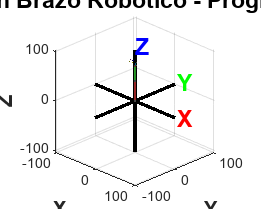

a1=0;
ap1=90;
d1=0;
t1=q_brazo(1);

A1=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
    sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
    0,sind(ap1),cosd(ap1),d1;...
    0,0,0,1];

### Abducción y aducción vertical del hombro

a1=0; 
ap1=0; 
d1=0; 
t1=q_brazo(2);
A1v=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
     sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
     0,sind(ap1),cosd(ap1),d1;...
     0,0,0,1];
MA = A1*A1v;

### Segundo grado de libertad: Flexión y extensión de hombro

a1=L_brazo(1); 
ap1=0; d1=0; 

if q_brazo(3)==0

t1=q_brazo(3)+ 90;
A2=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
    sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
    0,sind(ap1),cosd(ap1),d1;...
    0,0,0,1];
else
t1=(q_brazo(3)-q_brazo(2)) + 90;
A2=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
    sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
    0,sind(ap1),cosd(ap1),d1;...
    0,0,0,1];
MA = A1*A1v*A2;
P1 = MA(1:3,4);
dibujarCilindro([0,0,0], P1', R_segmentos(1), [0.8 0.2 0.2]);
end

MA = A1*A1v*A2;
P1 = MA(1:3,4);
dibujarCilindro([0,0,0], P1', R_segmentos(1), [0.8 0.2 0.2]);

### Tercer grado de libertad: Flexión y extensión del codo

a1=L_brazo(2);
ap1=0;
d1=0;
t1=q_brazo(4);

A3=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
    sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
    0,sind(ap1),cosd(ap1),d1;...
    0,0,0,1];

MA = A1*A1v*A2*A3;
P2 = MA(1:3,4);
dibujarCilindro(P1', P2', R_segmentos(2), [0.2 0.8 0.2]);
dibujarEsfera(P1', R_articulaciones(2), [0.3 0.3 0.3]);

### Cuarto grado de libertad: Rotación de muñeca

a1=0; 
ap1=180; 
d1=0; 
t1=q_brazo(5);
A4=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
    sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
    0,sind(ap1),cosd(ap1),d1;...
    0,0,0,1];


dibujarEsfera(P2', R_articulaciones(3), [0.3 0.3 0.3]);

### Cadena cinemática adicional: Mano 

colores_dedos = {
    [0 0 0.8];      % Corazón - Azul
    [0 0.6 0.8];    % Índice - Cian
    [0.8 0 0.8];    % Anular - Magenta
    [0.8 0.8 0];    % Meñique - Amarillo
    [0.8 0.4 0]     % Pulgar - Naranja
};

for dedo_idx = 1:5
    longitud_base = L_dedos_base(dedo_idx);
    angulo_base = q_dedos_base(dedo_idx);
    angulo_abduccion = q_abduccion(dedo_idx);
    angulo_proximal = q_proximal(dedo_idx);
    angulo_distal = q_distal(dedo_idx);
    color_dedo = colores_dedos{dedo_idx};

#### Metacarpo

    a1=longitud_base;
    ap1=0;  
    d1=0;
    t1=angulo_base;

    A5=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
        sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
        0,sind(ap1),cosd(ap1),d1;...
        0,0,0,1];

    MA=A1*A1v*A2*A3*A4*A5;
    P3=MA(1:3,4);
    dibujarCilindro(P2', P3', R_segmentos(3), color_dedo);

#### Falanges

- Abducción

    a1=0;
    ap1=-90;  
    d1=0;
    t1=angulo_abduccion;

    A6=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
        sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
        0,sind(ap1),cosd(ap1),d1;...
        0,0,0,1];

2. Flexión de falange proximal

    a1=L_falanges(1);
    ap1=0;  
    d1=0;
    t1=angulo_proximal;

    A7=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
        sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
        0,sind(ap1),cosd(ap1),d1;...
        0,0,0,1];

    MA=A1*A1v*A2*A3*A4*A5*A6*A7;
    P4=MA(1:3,4);
    dibujarCilindro(P3', P4', R_segmentos(4), color_dedo*0.9);
    dibujarEsfera(P3', R_articulaciones(4), [0.4 0.4 0.4]);

3. Flexión de falange distal

    a1=L_falanges(2);
    ap1=-90;  
    d1=0;
    t1=angulo_distal;

    A8=[cosd(t1),-sind(t1)*cosd(ap1),sind(t1)*sind(ap1),a1*cosd(t1);...
        sind(t1),cosd(t1)*cosd(ap1),-cosd(t1)*sind(ap1),a1*sind(t1);...
        0,sind(ap1),cosd(ap1),d1;...
        0,0,0,1];

   MA=A1*A1v*A2*A3*A4*A5*A6*A7*A8;
    P5=MA(1:3,4);
    dibujarCilindro(P4', P5', R_segmentos(5), color_dedo*0.8);
    dibujarEsfera(P4', R_articulaciones(5), [0.4 0.4 0.4]);
    dibujarEsfera(P5', R_articulaciones(5)*0.9, color_dedo*0.7);
end

dibujarEsfera([0,0,0], R_articulaciones(1), [0.3 0.3 0.3]);

drawnow
%pause(0.1)

end

## Funciones

function dibujarCilindro(p1, p2, radio, color)
    v = p2 - p1;
    longitud = norm(v);
    
    if longitud < 0.001
        return;
    end
    
    [X, Y, Z] = cylinder(radio, 20);
    Z = Z * longitud;
    
    v_norm = v / longitud;
    theta = acosd(v_norm(3));
    
    if abs(v_norm(3)) < 0.9999
        eje = cross([0 0 1], v_norm);
        eje = eje / norm(eje);
    else
        eje = [1 0 0];
        theta = 0;
    end
    
    if theta > 0.001
        K = [0 -eje(3) eje(2); eje(3) 0 -eje(1); -eje(2) eje(1) 0];
        R = eye(3) + sind(theta)*K + (1-cosd(theta))*K*K;
    else
        R = eye(3);
    end
    
    for idx = 1:numel(X)
        punto = [X(idx); Y(idx); Z(idx)];
        punto_rot = R * punto + p1';
        X(idx) = punto_rot(1);
        Y(idx) = punto_rot(2);
        Z(idx) = punto_rot(3);
    end
    
    surf(X, Y, Z, 'FaceColor', color, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
end

function dibujarEsfera(centro, radio, color)
    [X, Y, Z] = sphere(15);
    X = X * radio + centro(1);
    Y = Y * radio + centro(2);
    Z = Z * radio + centro(3);
    
    surf(X, Y, Z, 'FaceColor', color, 'EdgeColor', 'none', 'FaceAlpha', 0.95);
end
